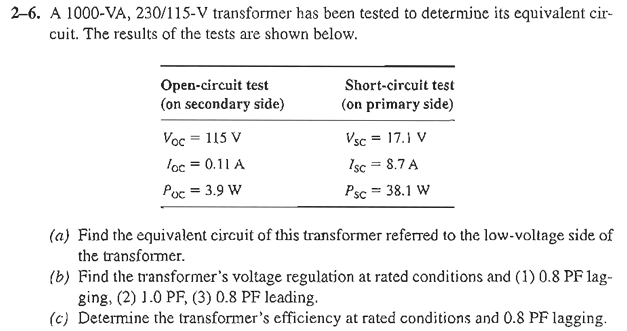

一個 1000-VA、230/115-V 的變壓器已經進行了測試，以確定其等效電路。測試結果如下表所示。

(a) 求此變壓器的等效電路參數，並以低壓側為基準。

(b) 求此變壓器在額定條件下的電壓調整率，功率因數分別為 (1) 0.8 滯後、(2) 1.0、(3) 0.8 超前。

(c) 求此變壓器在額定條件和 0.8 滯後功率因數下的效率。

% 變壓器參數(已知)
V_OC = 115;   % 開路電壓 (V)
I_OC = 0.11;  % 開路電流 (A)
P_OC = 3.9;   % 開路功率 (W)

V_SC = 17.1;  % 短路電壓 (V)
I_SC = 8.7;   % 短路電流 (A)
P_SC = 38.1;  % 短路功率 (W)

S_rated = 1000; % 視在功率 (VA)
Vs_rated = 115;

% 變壓器的電壓轉換比為 230 V / 115 V
V_HV = 230; % 高壓端(一次側)電壓，V (230V)
V_LV = 115; % 低壓端(二次側)電壓，V (115V)

% (a) 求等效電路參數
thetaOc = acos(P_OC / (V_OC * I_OC));
disp(['thetaOc = ',num2str(thetaOc * 180/pi)]);

thetaOc = 72.0432


YE = I_OC / V_OC;
[Gc, Bm] = pol2cart(thetaOc, YE);
% disp(['YE = ', num2str(Gc), ' + j', num2str(Bm)]);
Rc = 1/Gc;
Xm = 1/Bm;
% disp(['Zc = ', num2str(Rc), ' + j', num2str(Xm)]);

% Short-cricuit test
thetaSc = acos(P_SC / (V_SC * I_SC));
% disp(['thetaSc = ',num2str(thetaSc * 180/pi)]);
ZSE = V_SC / I_SC;
[Req, Xeq] = pol2cart(thetaSc, ZSE);
% disp(['ZSE = ', num2str(Req), ' + j', num2str(Xeq)]);

% 顯示結果
fprintf('(a) 等效電路參數:\n');

(a) 等效電路參數:


fprintf('開路電阻 Rc = %.2f Ω\n', Rc);

開路電阻 Rc = 3391.03 Ω


fprintf('開路電抗 Xm = %.2f Ω\n', Xm);

開路電抗 Xm = 1098.99 Ω


fprintf('等效電阻 Req = %.2f Ω\n', Req);

等效電阻 Req = 0.50 Ω


fprintf('等效電抗 Xeq = %.2f Ω\n', Xeq);

等效電抗 Xeq = 1.90 Ω


(b) 求電壓調整率

a = V_HV / V_LV;
Req = Req / a^2;
Xeq = Xeq / a^2;

Is_rated = S_rated / Vs_rated;
disp(['Is_rated = ', num2str(real(Is_rated)), ' + j', num2str(imag(Is_rated))]);

Is_rated = 8.6957 + j0


[theta, Is_rated_mag] = cart2pol(real(Is_rated), imag(Is_rated));
disp(['Is_rated = ', num2str(Is_rated_mag), ' /_', num2str(theta * 180/pi)]);

Is_rated = 8.6957 /_0



%% 功率因數 (滯後: 0.8, 1.0, 超前: -0.8)

% PF = 0.8 lagging
PF_lagging = 0.8;
Is_rated_lagging = conj(Is_rated * exp(1j * (acos(PF_lagging))));
disp(['Is_rated_lagging = ', num2str(real(Is_rated_lagging)), ' + j', num2str(imag(Is_rated_lagging))]);

Is_rated_lagging = 6.9565 + j-5.2174


% [theta, Is_rated_lagging_deg] = cart2pol(real(Is_rated_lagging), imag(Is_rated_lagging));
% disp(['Is_rated_lagging = ', num2str(Is_rated_lagging_deg), ' /_', num2str(theta * 180/pi)]);
% caluate VP's magnitude and phase
VP_lagging = Vs_rated + Req * Is_rated_lagging + Xeq * exp(1j * (pi/2)) * Is_rated_lagging;
disp(['Vp_lagging = ', num2str(real(VP_lagging)), ' + j', num2str(imag(VP_lagging))]);

Vp_lagging = 118.3536 + j2.6477


[theta_lagging, VP_lagging_mag] = cart2pol(real(VP_lagging), imag(VP_lagging));
disp(['VP_lagging = ', num2str(VP_lagging_mag), ' /_', num2str(theta_lagging * 180/pi)]);

VP_lagging = 118.3833 /_1.2816


VR_lagging = (VP_lagging_mag - Vs_rated) / Vs_rated;
disp(['VR_lagging = ', num2str(VR_lagging * 100), ' %']);

VR_lagging = 2.942 %



% PF = 1.0
PF = 1;
disp(['Is_rated = ', num2str(Is_rated_mag), ' /_', num2str(theta * 180/pi)]);

Is_rated = 8.6957 /_0


% caluate VP's magnitude and phase
VP = Vs_rated + Req * Is_rated + Xeq * exp(1j * (pi/2)) * Is_rated;
disp(['Vp = ', num2str(real(VP)), ' + j', num2str(imag(VP))]);

Vp = 116.0943 + j4.1304


[theta, VP] = cart2pol(real(VP), imag(VP));
disp(['VP = ', num2str(VP), ' /_', num2str(theta * 180/pi)]);

VP = 116.1677 /_2.0376


VR = (VP - Vs_rated) / Vs_rated;
disp(['VR = ', num2str(VR * 100), ' %']);

VR = 1.0154 %



% PF = 0.8 leading
PF_leading = 0.8;
Is_rated_leading = Is_rated * exp(1j * (acos(PF_leading)));
disp(['Is_rated_leading = ', num2str(real(Is_rated_leading)), ' + j', num2str(imag(Is_rated_leading))]);

Is_rated_leading = 6.9565 + j5.2174


% caluate VP's magnitude and phase
VP_leading = Vs_rated + Req * Is_rated_leading + Xeq * exp(1j * (pi/2)) * Is_rated_leading;
disp(['Vp_leading = ', num2str(real(VP_leading)), ' + j', num2str(imag(VP_leading))]);

Vp_leading = 113.3972 + j3.9609


[theta_leading, VP_leading_mag] = cart2pol(real(VP_leading), imag(VP_leading));
disp(['VP_leading = ', num2str(VP_leading_mag), ' /_', num2str(theta_leading * 180/pi)]);

VP_leading = 113.4664 /_2.0005


VR_leading = (VP_leading_mag - Vs_rated) / Vs_rated;
disp(['VR_leading = ', num2str(VR_leading * 100), ' %']);

VR_leading = -1.3336 %


(c)

% 計算系統效率
% PF = 0.8 lagging
P_out = Vs_rated * Is_rated * PF_lagging;
% 銅損耗
P_loss_cu = Is_rated^2 * Req;
% 鐵芯損耗
P_loss_core = VP_lagging_mag^2 / Rc;
P_loss = P_loss_cu + P_loss_core;
P_in = P_out + P_loss;
efficiency = (P_out / P_in) * 100;
fprintf('系統效率: %.2f%%\n', efficiency);

系統效率: 98.32%
